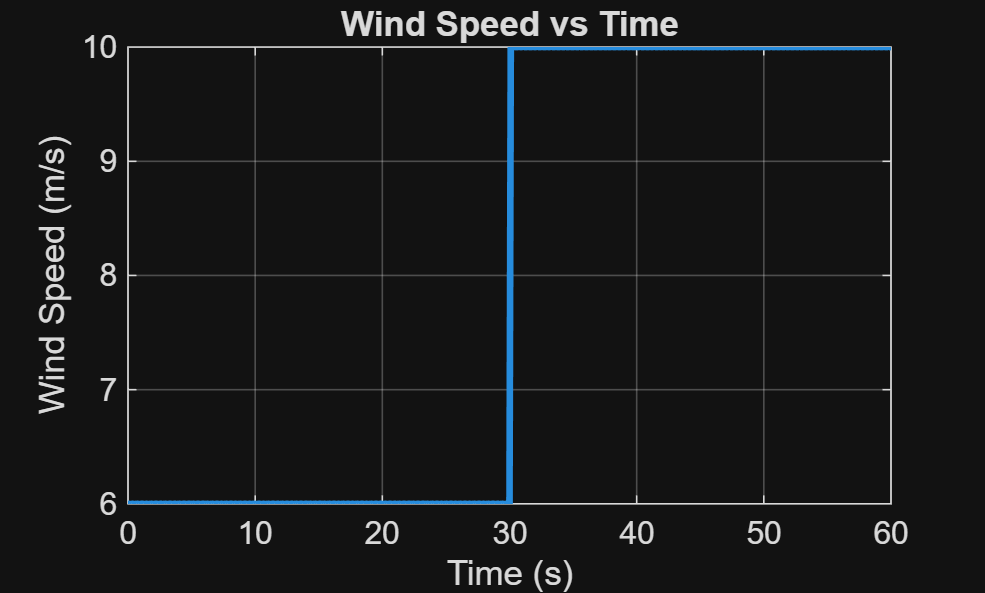

clc; clear; close all;

% Time vector
t = 0:0.1:60;   % seconds

% --- Wind Speed Models ---
% Option 1: Constant wind
% v = 8 * ones(size(t));

% Option 2: Step change in wind speed
v = 6 + 4*(t > 30);   % 6 m/s, jumps to 10 m/s at t = 30 s

% Option 3: Sinusoidal wind (uncomment to use)
% v = 8 + 2*sin(0.2*t);

% --- Constants ---
rho = 1.225;     % air density (kg/m^3)
R = 2;           % blade radius (m)
A = pi * R^2;    % swept area (m^2)
Cp = 0.4;        % power coefficient (efficiency)

% --- Power Calculation ---
P = 0.5 * rho * A * Cp .* (v.^3);

% --- Average Power ---
P_avg = mean(P);

% --- Plot Wind Speed ---
figure;
plot(t, v, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Wind Speed (m/s)');
title('Wind Speed vs Time');
grid on;

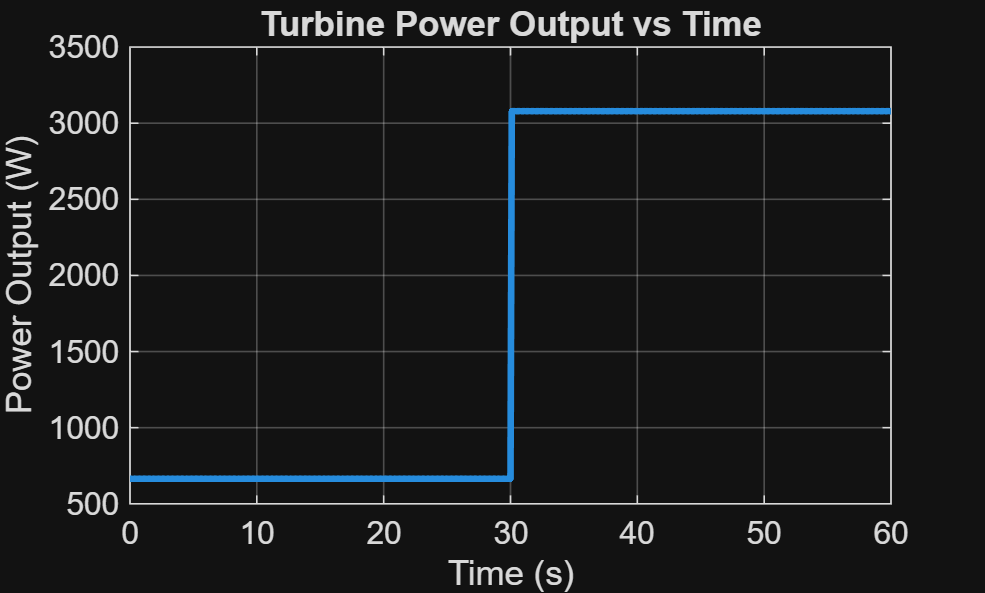


% --- Plot Power Output ---
figure;
plot(t, P, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Power Output (W)');
title('Turbine Power Output vs Time');
grid on;


% --- Display Average Power ---
fprintf('Average Power Output = %.2f W\n', P_avg);

Average Power Output = 1869.88 W
